nu = 1;
startAngel = 30;
Amplitude = 1;
sim('kapitsa_pendulum.slx', 15);

Unable to find system or file 'kapitsa_pendulum.slx'.

theta_down = Theta_values;
dtheta_down = dTheta_values;
x_down = x_values;
y_down = y_values;

nu = 15;
startAngel = 170;
Amplitude = 1;
sim('kapitsa_pendulum.slx', 5);
theta_up = Theta_values;
dtheta_up = dTheta_values;
x_up = x_values;
y_up = y_values;

fg1 = figure;
set(fg1, "Visible", "on");
hold all;
plot(x_down, y_down);
plot(x_up, y_up);
xlabel('X');
ylabel('Y');
grid on
grid minor
legend('Положение равновесия внизу', 'Положение равновесия вверху')
hold off;

fg2 = figure;
set(fg2, "Visible", "on");
hold all;
plot(theta_down, dtheta_down);
plot(theta_up, dtheta_up);
xlabel('X');
ylabel('Y');
grid on
grid minor
legend('Положение равновесия внизу', 'Положение равновесия вверху')
hold off;

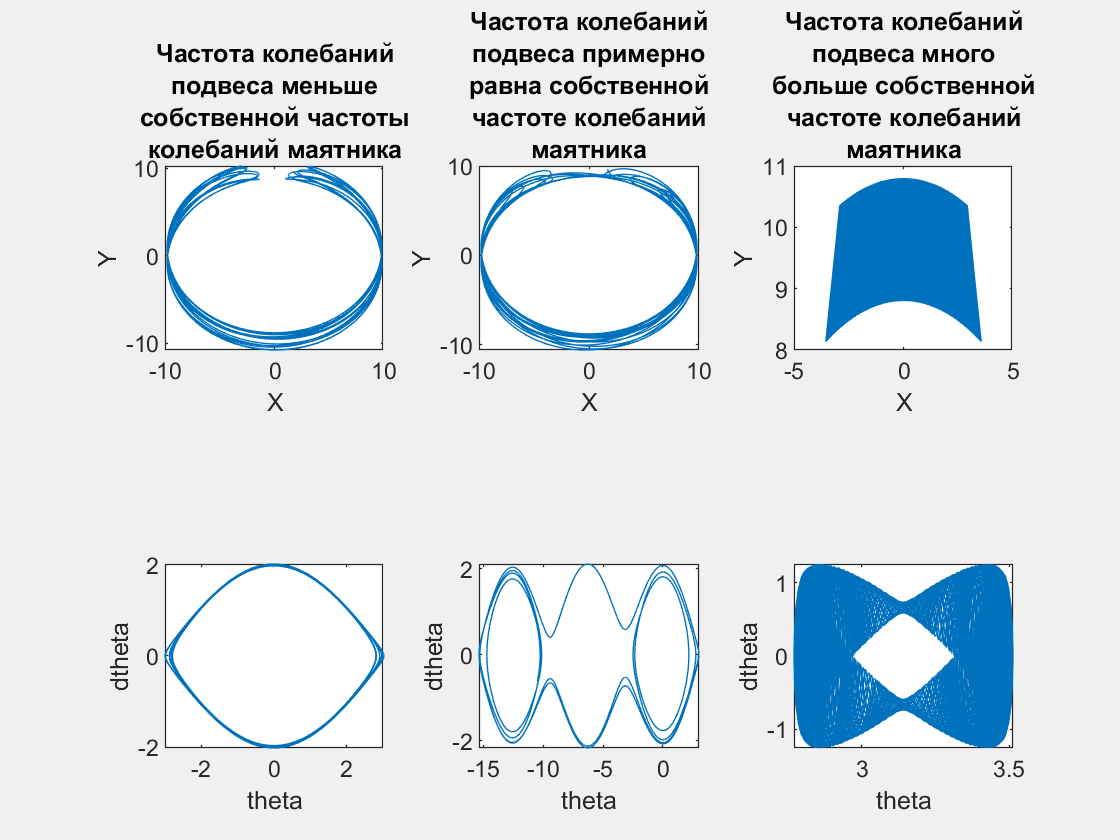

nu_arr = [0.08, 0.16, 5];
titl = {
    sprintf('Частота колебаний\nподвеса меньше\nсобственной частоты\nколебаний маятника'),
    sprintf('Частота колебаний\nподвеса примерно\nравна собственной\nчастоте колебаний\nмаятника'),
    sprintf('Частота колебаний\nподвеса много\nбольше собственной\nчастоте колебаний\nмаятника')
};
startAngel = 170;
Amplitude = 1;
fg = figure;
set(fg, "Visible", "on");

for i = 1 : 3
    nu = nu_arr(i);
    sim('kapitsa_pendulum.slx', 100);
    theta_i = Theta_values;
    dtheta_i = dTheta_values;
    x_i = x_values;
    y_i = y_values;

    ax_i = subplot(2, 3, i);
    plot(x_i, y_i);
    xlabel('X');
    ylabel('Y');
    title(titl{i});

    ax_3i = subplot(2, 3, i+3);
    plot(theta_i, dtheta_i);
    xlabel('theta');
    ylabel('dtheta');
end


nu = 2;
startAngel = 30;
Amplitude = 1;
sim('kapitsa_pendulum.slx', 100);
theta_up = Theta_values;
dtheta_up = dTheta_values;
x_up = x_values;
y_up = y_values;